**LEP 6-31: Equilibrium Conversion in a Semi batch Reactor**

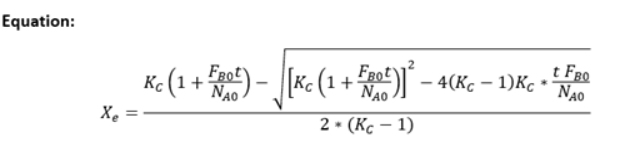

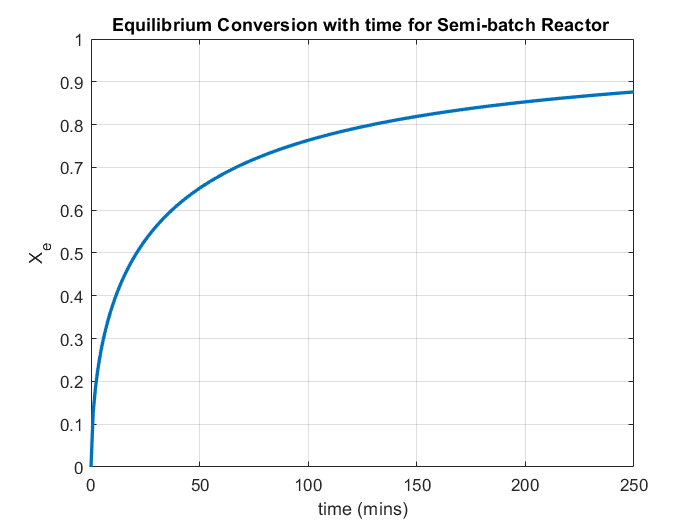


Kc=0.05; 
FB0 = 0.05;  
NA0 = 0.1; 
t=linspace(0,250,250);
z=size(t);
D1 = 2*(Kc - 1);
for i=1:250
N1(i) = Kc*(1 + FB0*t(i)/NA0);
N2(i) = 4*(Kc - 1)*Kc*t(i)*FB0/NA0;
Xe(i) = (N1(i) - sqrt((N1(i).^2) - N2(i)))/(D1);
end
plot(t,Xe,'LineWidth',2)
xlabel('time (mins)')
ylabel('X_e')
axis([0 250 0 1])
title('Equilibrium Conversion with time for Semi-batch Reactor ')
grid on